clc, clear all, close all;

path = pwd + "/15bpm3c40sps_2-00sw/";
t_fullpath = join([path, "17_mahalanobis.csv"], "");
t_num = readmatrix(t_fullpath);

r_fullpath = join([path, "17_rawvals.csv"], "");
r_num = readmatrix(r_fullpath);

t_time = t_num(:, 3);
t_dist = t_num(:, 2);
t_avg = mean(t_dist);

%ids = ["e280116060000205403ddcdb", "e280116060000209e445f02a"] % sim tags
ids = ["e280116060000205403de047", "e280116060000205403e136b"]; % DYSE tags
epc = readtable(r_fullpath).epc96(:);

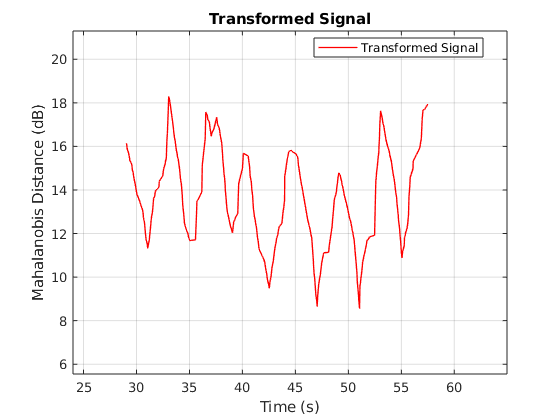


r_time = r_num(:, 3);
r_time = r_time(epc == ids(1));
r_rssi = r_num(:, 2);
r_rssi = r_rssi(epc == ids(1));

range = max([max(t_dist) - min(t_dist) ...
    max(r_rssi) - min(r_rssi)]);
r_min_y = min(r_rssi) - (max(r_rssi) - min(r_rssi) - range) / 2 - 3;
r_max_y = max(r_rssi) - (max(r_rssi) - min(r_rssi) - range) / 2 + 3;
t_min_y = min(t_dist) - (max(t_dist) - min(t_dist) - range) / 2 - 3;
t_max_y = max(t_dist) - (max(t_dist) - min(t_dist) - range) / 2 + 3;

min_x = min(r_time) - 5;
max_x = max(r_time) + 5;

figure;
plot(t_time, t_dist, 'red', 'linewidth', 1);
xlabel('Time (s)'), ylabel('Mahalanobis Distance (dB)');
grid on, title('Transformed Signal');
ylim([t_min_y, t_max_y]);
xlim([min_x, max_x]);
%yline(t_avg);
legend('Transformed Signal', 'location', 'best');

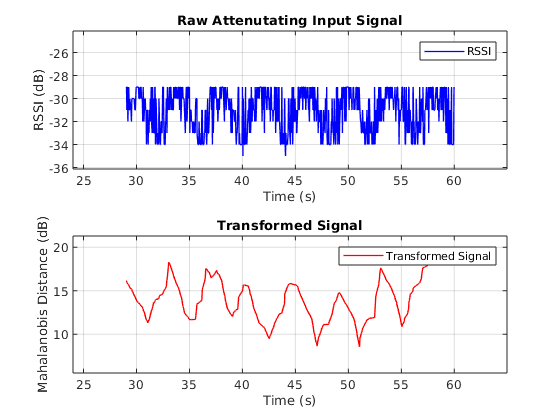


figure;
tiledlayout(2, 1);

ax1 = nexttile;
plot(r_time, r_rssi, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location","best");
xlim([min_x, max_x]);
ylim([r_min_y, r_max_y]);

ax2 = nexttile;
plot(ax2, t_time, t_dist, 'red', 'linewidth', 1);
xlabel('Time (s)'), ylabel('Mahalanobis Distance (dB)');
grid on, title('Transformed Signal');
ylim([t_min_y, t_max_y]);
xlim([min_x, max_x]);
%yline(t_avg);
legend('Transformed Signal', 'location', 'best');